load('Amazonas.mat');

ydata = ydata(:, 10:end)';
ydata = [ydata(:,3), ydata(:,2), ydata(:,1)];

D = length(ydata);
Domain = [0 D-1];
xdata = 0 : D-1;

**Create the model as a table for GSUA-CSB toolbox implementation**

Define the model as a symbolic structure

syms S(t) I(t) R(t) D(t) A(t) E(t) Q(t) C(t)
syms alpha beta delta eta tau epsilon mu gamma k lambda nu z sigma

N = S + C + E + A + I + Q + R + D;

ode1 = diff(S) == -alpha*S - beta*I/N*S - sigma*S*A/N - eta*S;
ode2 = diff(A) ==  -tau*A + epsilon*E;
ode3 = diff(C) == alpha*S - mu*C;
ode4 = diff(E) == -gamma*E + beta*I/N*S + mu*C + eta*S + sigma*S*A/N - epsilon*E;
ode5 = diff(I) == tau*A + gamma*E - delta*I;
ode6 = diff(R) == lambda*Q;
ode7 = diff(Q) == delta*I - lambda*Q - k*Q;
ode8 = diff(D) == k*Q;

odes = [ode1; ode2; ode3; ode4; ode5; ode6; ode7; ode8];
vars = [R D I S A C E Q];

opts = odeset('NonNegative',1:8);

Then, define the factor intervals with their corresponding names.

Range1 = [  ydata(1,1) ydata(1,1);  %R
            ydata(1,2) ydata(1,2);  %D    
            ydata(1,3) ydata(1,3);  %I
            7600 80000;             %S
            0 2000;                 %A
            0 1000;                 %C
            0 2000;                 %E
            0 2000                  %Q
];

Range2 = [  0 2;    %alpha
            0 10;   %beta  
            0 1;    %delta
            0 5;    %epsilon
            0 1;    %eta
            0 1;    %gamma
            0 1;    %k
            0 1;    %lambda
            0 1;    %mu
            0 10;   %sigma    
            0 6;    %tau
]; 

Range = [Range1; Range2];


Finally, use the gsua_dpmat to create the functional table

outs = [1,3];
[T,~] = gsua_dpmat(odes,vars,[0 90],'Model','output',outs,'opt',opts,'Range',Range);

Introduce ranges in the following order: 


$$ans = \left(\begin{array}{ccccccccccccccccccc} R\left(t\right) & \text{D}\left(t\right) & \text{I}\left(t\right) & S\left(t\right) & A\left(t\right) & C\left(t\right) & \text{E}\left(t\right) & Q\left(t\right) & \alpha & \beta & \delta & \epsilon & \eta & \gamma & k & \lambda & \mu & \sigma & \tau \end{array}\right)$$

% domain=[0 90 0.01]%add a third column with fixed step size to domain variable
% [T,sol] = gsua_dataprep(odes,vars,domain,'Model','solver','ode4');
T.Row = ["S(0)", "A(0)", "C(0)", "E(0)", "Q(0)",...
    "\alpha", "\beta", "\delta", "\epsilon", "\eta", "\gamma", "k", "\lambda", "\mu", "\sigma",  "\tau"];

Define the nominal curve as the best factor estimation

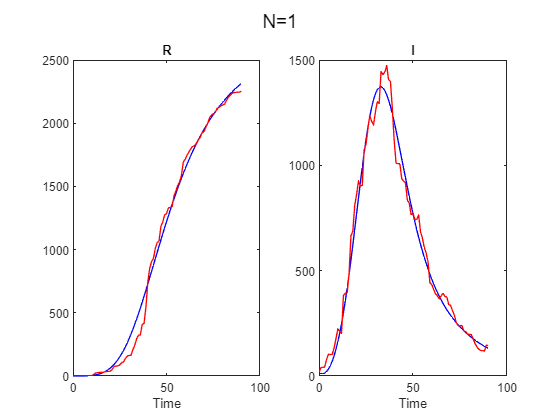

load('Results/Estimations/Deepest_Amazonas.mat')
T.Nominal = Deep;
gsua_eval(T.Nominal, T, xdata, ydata(:,outs)');

**Perform the once-at-time (OAT) algorithm before CSB estimation**

T_oat = gsua_oatr2(T, 'parallel', false, 'correct', false);

Expansion-reduction Method OAT is being launched
------------------------------------
Calculus of \tau Starting
Range for \tau Done!
Initial range of \tau(16)--> 0  6
Actual range --> 0.085311     0.34522
Calculus of \sigma Starting
Activating intern_counter for \sigma
Activating intern_counter for \sigma
Range for \sigma Done!
Initial range of \sigma(15)--> 0  10
Actual range --> 0   0.0011365
Calculus of \mu Starting
Range for \mu Done!
Initial range of \mu(14)--> 0  1
Actual range --> 0.016465    0.084005
Calculus of \lambda Starting
Range for \lambda Done!
Initial range of \lambda(13)--> 0  1
Actual range --> 0.00474    0.010723
Calculus of k Starting
Range for k Done!
Initial range of k(12)--> 0  1
Actual range --> 0.042028      0.1231
Calculus of \gamma Starting
Activating intern_counter for \gamma
Activating intern_counter for \gamma
Range for \gamma Done!
Initial range of \gamma(11)--> 0  1
Actual range --> 0  0.00014773
Calculus of \eta Starting
Activating intern_counter for \

T_oat

T_oat = 16×2 table
                         Range              Nominal  
                _______________________    __________

    S(0)            18427         34602         26573
    A(0)                0        1.2063       0.53615
    C(0)                0        26.982        11.992
    E(0)                0        59.569        26.475
    Q(0)                0       0.29657       0.13181
    \alpha      0.0062015       0.17427      0.027888
    \beta         0.50953        2.4291        1.3637
    \delta        0.36726       0.67658       0.47274
    \epsilon      0.12449        1.7808       0.31364
    \eta                0     0.0016015    0.00071179
    \gamma              0    0.00014773    6.5657e-05
    k       

NRange=T_oat.Range;
load Results\CSB\CSBRangeProtected_skewness_N_160.mat
deviationsL = std((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5

deviationsL =     0.1391
    0.2431
    0.2358
    0.2409
    0.2298
    0.0408
    0.1191
    0.1088
    0.0438
    0.2304


deviationsU = std((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5

deviationsU =     0.1470
    0.2368
    0.2397
    0.2312
    0.2437
    0.1090
    0.1631
    0.1395
    0.1477
    0.2688


meanL =  mean((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2)

meanL =     0.3787
    0.2120
    0.2040
    0.2013
    0.2065
    0.0727
    0.2187
    0.2067
    0.0310
    0.1978


meanU =  mean((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2)

meanU =     0.7779
    0.7832
    0.7806
    0.7470
    0.7730
    0.2910
    0.6442
    0.5904
    0.2493
    0.7653


load Results\CSB\CSBRangeProtected_skewness_N_500.mat
deviationsL(:,2) = std((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
deviationsU(:,2) = std((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
meanL(:,2) =  mean((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
meanU(:,2) = mean((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
load Results\CSB\CSBRangeProtected_skewness_N_1000.mat
deviationsL(:,3) = std((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
deviationsU(:,3) = std((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
meanL(:,3) =  mean((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
meanU(:,3) = mean((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
load Results\CSB\CSBRangeProtected_skewness_N_2000.mat
deviationsL(:,4) = std((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
deviationsU(:,4) = std((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
meanL(:,4) =  mean((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
meanU(:,4) = mean((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
load Results\CSB\CSBRangeProtected_skewness_N_5000.mat
deviationsL(:,5) = std((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
deviationsU(:,5) = std((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
meanL(:,5) =  mean((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
meanU(:,5) = mean((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);

1-mean((deviationsL+deviationsU)/2)

ans =     0.8301    0.8854    0.9388    0.9454    0.9483


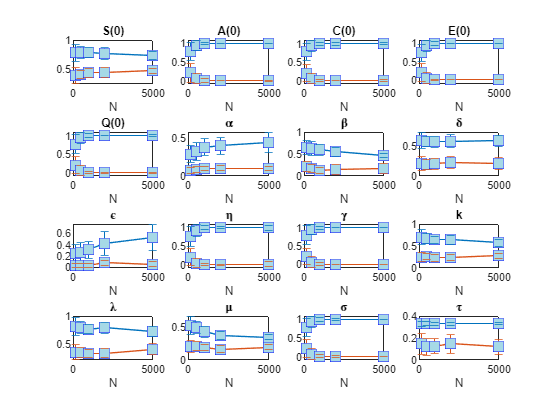

figure(1)
clf
for i=1:16
    subplot(4,4,i)
    errorbar([140,500,1000,2000,5000],meanU(i,:),deviationsU(i,:),"-s","MarkerSize",10,...
        "MarkerEdgeColor","blue","MarkerFaceColor",[0.65 0.85 0.90])
    hold on
    errorbar([140,500,1000,2000,5000],meanL(i,:),deviationsL(i,:),"-s","MarkerSize",10,...
        "MarkerEdgeColor","blue","MarkerFaceColor",[0.65 0.85 0.90])
    title(T.Properties.RowNames{i})
    xlabel('N')
end

load Results\CSB\CSBRangeUnProtected_skewness_N_160.mat
deviationsL(:,1) = std((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
deviationsU(:,1) = std((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
meanL(:,1) =  mean((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
meanU(:,1) = mean((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
load Results\CSB\CSBRangeUnProtected_skewness_N_500.mat
deviationsL(:,2) = std((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
deviationsU(:,2) = std((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
meanL(:,2) =  mean((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
meanU(:,2) = mean((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
load Results\CSB\CSBRangeUnProtected_skewness_N_1000.mat
deviationsL(:,3) = std((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
deviationsU(:,3) = std((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
meanL(:,3) =  mean((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
meanU(:,3) = mean((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
load Results\CSB\CSBRangeUnProtected_skewness_N_2000.mat
deviationsL(:,4) = std((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
deviationsU(:,4) = std((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
meanL(:,4) =  mean((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
meanU(:,4) = mean((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
load Results\CSB\CSBRangeUnProtected_skewness_N_5000.mat
deviationsL(:,5) = std((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
deviationsU(:,5) = std((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
meanL(:,5) =  mean((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
meanU(:,5) = mean((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);

1-mean((deviationsL+deviationsU)/2)

ans =     0.8190    0.8835    0.9265    0.9322    0.9387


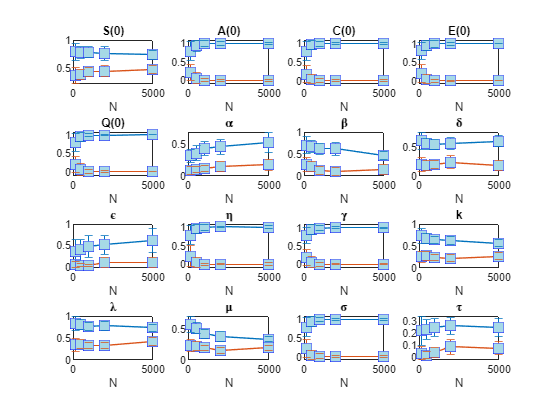

figure(2)
clf
for i=1:16
    subplot(4,4,i)
    errorbar([140,500,1000,2000,5000],meanU(i,:),deviationsU(i,:),"-s","MarkerSize",10,...
        "MarkerEdgeColor","blue","MarkerFaceColor",[0.65 0.85 0.90])
    hold on
    errorbar([140,500,1000,2000,5000],meanL(i,:),deviationsL(i,:),"-s","MarkerSize",10,...
        "MarkerEdgeColor","blue","MarkerFaceColor",[0.65 0.85 0.90])
    title(T.Properties.RowNames{i})
    xlabel('N')
end

%obj=@(pars) (gsua_deval(pars,T,xdata)-ydata(:,[1,3])')./std(ydata(:,[1,3]))';
[x,resnorm,residual,exitflag,output,lambda,jacobian] = lsqcurvefit(@(pars,xaxis) gsua_deval(pars,T,xaxis),T.Nominal',xdata,ydata(:,[1,3])',T.Range(:,1),T.Range(:,2));


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


%[x,resnorm,residual,exitflag,output,lambda,jacobian] = lsqnonlin(obj,T.Nominal',T.Range(:,1),T.Range(:,2));

ci = nlparci(x,residual,'jacobian',jacobian)

ci = 1.0e+06 *

   -1.5279    1.5810
   -0.0028    0.0028
   -0.3449    0.3449
   -0.0041    0.0041
   -0.0000    0.0000
   -0.0000    0.0000
   -0.0002    0.0002
   -0.0000    0.0000
   -0.0000    0.0000
   -0.0000    0.0000


t2=table(x(:));
t2.Nominal=T.Nominal;
t2.Ci=ci

t2 = 16×3 table
       Var1        Nominal                  Ci            
    __________    __________    __________________________

         26573         26573    -1.5279e+06      1.581e+06
       0.54025       0.53615        -2837.8         2838.9
            12        11.992    -3.4492e+05     3.4495e+05
        26.475        26.475        -4071.3         4124.2
       0.12988       0.13181        -20.303         20.563
      0.027893      0.027888       -0.60946        0.66524
        1.3637        1.3637        -154.08          156.8
       0.47274       0.47274        -24.165         25.111
       0.31367       0.31364        -17.619         18.246
    0.00071895    0.00071179       -0.47059        0.47202
    6.0788e-05    6.5657e-05        -4.1656         4.1657
      0.069119      0.069111       -0.32865        0.46689
     0.0076311     0.0076298       -0.39009        0.40